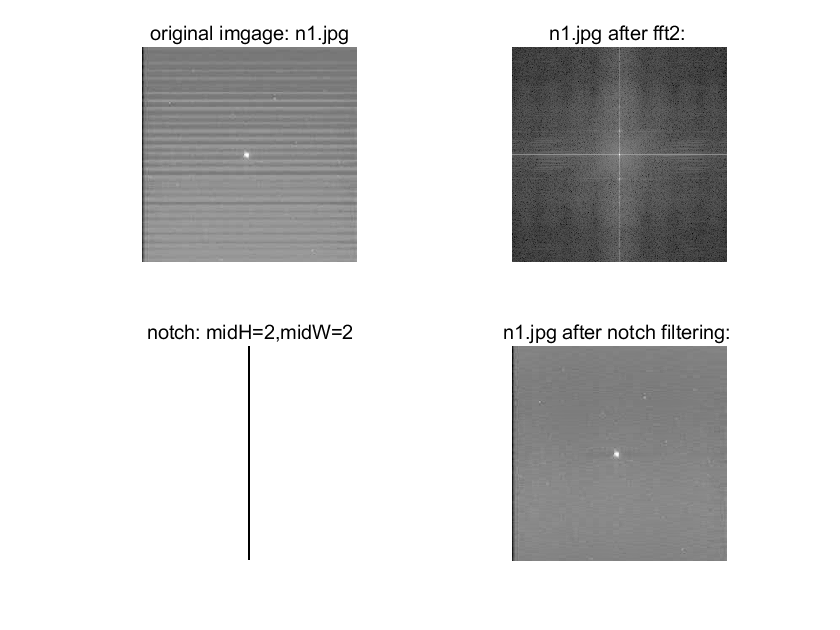

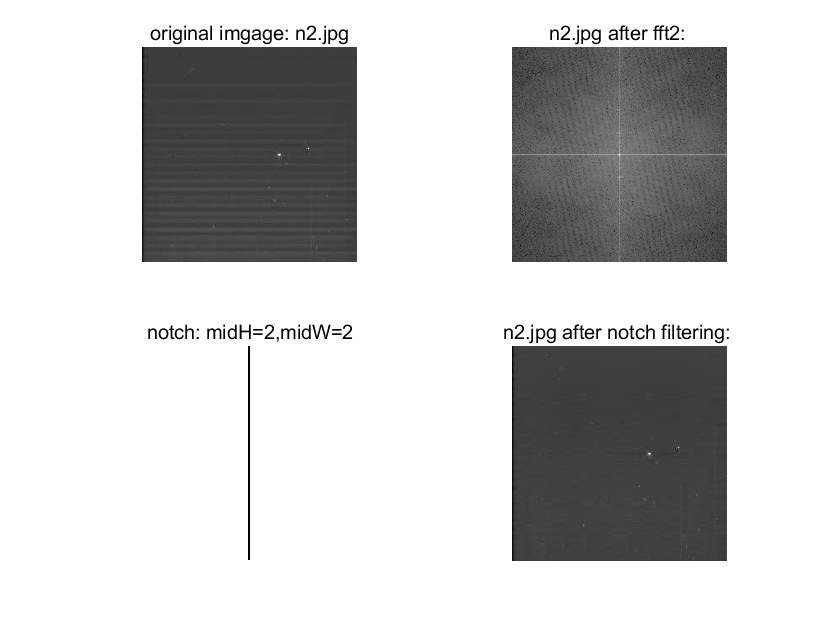

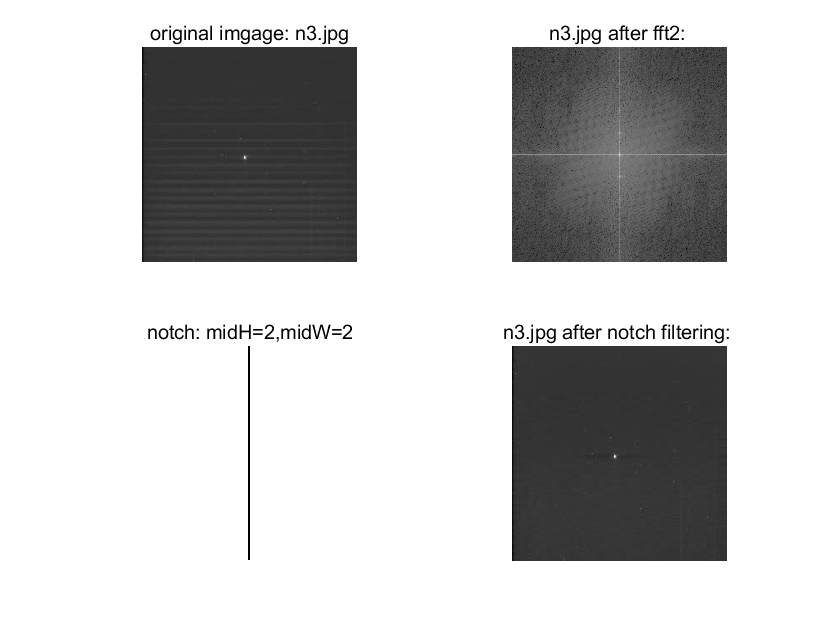

warning off;

img_dir = dir('img\'); % to process all the imgages in folder 'img\'
midH = 2; % the height of the retangular notch in the middle
midW = 2; % the width of the rectangle
for i = 1:length(img_dir)
    curr_file = img_dir(i);
    if ~isempty(strfind(curr_file.name, 'jpg'))...
        || ~isempty(strfind(curr_file.name, 'jpeg'))
        img_path = [img_dir(i).folder, '\', img_dir(i).name];
        img = imread(img_path);
        [output_img, H] = SinusoidalPatternRemoval(img, midH, midW);
        figure(i);
        subplot(2, 2, 1), imshow(img, []), title(['original imgage: ', img_dir(i).name]);
        subplot(2, 2, 2), imshow(log(fftshift(fft2(img))), []), title([img_dir(i).name, ' after fft2: ']);
        subplot(2, 2, 3), imshow(H, []), title(['notch: midH=', num2str(midH) ',midW=', num2str(midW)]);
        subplot(2, 2, 4), imshow(output_img, []), title([img_dir(i).name, ' after notch filtering: ']);
    end
end